## Code for training EEG and EMG classifiers

#### Load data

raw_eeg_data = load("data_sets\");

Error using load
Unable to read file 'data_sets\'. Input cannot be a directory.

eeg_fs=200; % EEG sample rate
raw_emg_data = load("data_sets\");
emg_fs=1000; % EMG sample rate

#### Display data lost

EEG

EMG

#### Display data quality

EEG

% Extract signal-to-noise (SNR), signal to noise and distortion ratio (SINAD), total harmonic distortion (THD).
sFE = signalTimeFeatureExtractor(SampleRate=eeg_fs, SNR = true, SINAD = true, THD = true);
eeg_quality = extract(sFE,data)

EMG

% Extract signal-to-noise (SNR), signal to noise and distortion ratio (SINAD), total harmonic distortion (THD).
sFE = signalTimeFeatureExtractor(SampleRate=eeg_fs, SNR = true, SINAD = true, THD = true);
emg_quality = extract(sFE,data)

#### Visualize signal

EEG

% Plot all EEG channels
EEG_plot_handle = tiledlayout(4,1);
channel1_plot_handle = nexttile;
plot(x1,y1)
title('Channel 1')
channel2_plot_handle = nexttile;
plot(x1,y1)
title('Channel 2')
channel3_plot_handle = nexttile;
plot(x1,y1)
title('Channel 3')
channel4_plot_handle = nexttile;
plot(x1,y1)
title('Channel 4')

% Link x axis
linkaxes([channel1_plot_handle,channel2_plot_handle,channel3_plot_handle,channel4_plot_handle],'x');

% Add title etc
title(EEG_plot_handle,'Raw EEG data')
xlabel(EEG_plot_handle,'Time (s)')
ylabel(EEG_plot_handle,'Voltage (v)')

EMG

% Plot all EMG channels
EMG_plot_handle = tiledlayout(2,1);
channel1_plot_handle = nexttile;
plot(x1,y1)
title('Channel 1')
channel2_plot_handle = nexttile;
plot(x1,y1)
title('Channel 2')

% Link x axis
linkaxes([channel1_plot_handle,channel2_plot_handle],'x');

% Add title etc
title(EMG_plot_handle,'Raw EMG data')
xlabel(EMG_plot_handle,'Time (s)')
ylabel(EMG_plot_handle,'Voltage (v)')

#### Preprocessing

EEG

Artifact removal: [https://se.mathworks.com/matlabcentral/fileexchange/55413-wica-data-varargin](https://se.mathworks.com/matlabcentral/fileexchange/55413-wica-data-varargin) 

Dependency: [https://github.com/biotrump/RADICAL-matlab](https://github.com/biotrump/RADICAL-matlab) 

Dependency: [https://research.ics.aalto.fi/ica/fastica/](https://research.ics.aalto.fi/ica/fastica/) 

%{
% Median filtering of the baseline wandering which usually is of a frequency of about 0.5Hz, but can be higher with movement.
% Baseline wandering is usually caused by respiration, electrodes(like poor contact or internal changes) and motion.
% The values 24 and 80 is for a sampling frequency of 500Hz.
s_filt_1=medfilt1(data,(eeg_fs/500)*24);
s_filt_2=medfilt1(s_filt_1,(eeg_fs/500)*80);
data = data - s_filt_2;
%}

% Remove baseline wandering and DC offset
% 4th order Butterworth highpass filter 0.1hz cut off frequency.
[n,d] = butter(4,(0.1)/(Fs/2),"high");
data = filter(n,d,data);

% Removal of 50Hz noise and all of it's harmonics up to 150Hz. 
% The noise is caused by magnetic fields generated by powerlines.
% Using a IIR notch filter of the fourth order as it's at that point the 50Hz noise peak on most signals practicaly becomes zero if a quality factor of about 25-35 is being used.
fo = 4;     % Filter order.
cf = 50/(eeg_fs/2); % Center frequency, value has to be between 0 and 1, where 1 is pi which is the Nyquist frequency which for our signal is Fs/2 = 500Hz.
qf = 30;   % Quality factor.
pbr = 1;   % Passband ripple, dB.
for k = 1:3
    notchSpecs  = fdesign.notch('N,F0,Q,Ap',fo,cf * k,qf,pbr);
    notchFilt = design(notchSpecs,'IIR','SystemObject',true);
    data = notchFilt(data); 
end

% Remove artifacts from EEG using wavelet enhanced ICA, W-ICA
[wIC,A,W,IC] = wICA(data,Fs = eeg_fs, wavename = "coif5")
% Artifacts
artifacts = A*wIC;
% Subtract artifacts from original signal to get "artifact free" signal
data = data - artifacts

EMG

% Removal of the 0Hz(the DC offset) and high frequency noise.
% 20–500Hz fourth-order Butterworth bandpass filter.
[n,d] = butter(4,[20 500]/(Fs/2),"bandpass");

data =     0.5990    0.9456    0.4835    0.7477    0.9841    0.4384    0.2310    0.0664    0.9727    0.0143    0.3261    0.2135    0.2574    0.9840    0.1384    0.0522    0.7042    0.2337    0.0307    0.7008    0.2684    0.3262    0.1443    0.1394    0.5371    0.9654    0.0729    0.5294    0.9189    0.0554    0.6709    0.3366    0.5053    0.4697    0.1113    0.2204    0.9580    0.4932    0.2099    0.2421    0.6419    0.8015    0.5671    0.3659    0.2453    0.7413    0.7299    0.1902    0.7711    0.3480
    0.9154    0.8946    0.4382    0.7829    0.9472    0.8046    0.3110    0.2975    0.9015    0.6826    0.5879    0.6830    0.0343    0.6083    0.9151    0.7057    0.4668    0.1766    0.1748    0.2356    0.8919    0.9822    0.7566    0.6229    0.6366    0.6896    0.9465    0.7190    0.6754    0.7409    0.9653    0.9502    0.5392    0.6338    0.8186    0.4847    0.4488    0.2654    0.5240    0.5968    0.1878    0.0100    0.4115    0.1233    0.0496    0.3045    0.9965    0.5533    0.5448  

ans =     0.5990    0.9456    0.4835    0.7477    0.9841    0.4384    0.2310    0.0664    0.9727    0.0143    0.3261    0.2135    0.2574    0.9840    0.1384    0.0522    0.7042    0.2337    0.0307    0.7008    0.2684    0.3262    0.1443    0.1394    0.5371    0.9654    0.0729    0.5294    0.9189    0.0554    0.6709    0.3366    0.5053    0.4697    0.1113    0.2204    0.9580    0.4932    0.2099    0.2421    0.6419    0.8015    0.5671    0.3659    0.2453    0.7413    0.7299    0.1902    0.7711    0.3480


data = filter(n,d,data);


segment =          0    0.6220    0.2391    0.4450    0.8029
         0    0.7200    0.1791    0.4556    0.7331
         0    0.8509    0.2885    0.2377    0.1019
         0    0.3032    0.5854    0.0631    0.4890
         0    0.7036    0.6687    0.5988    0.9825
         0    0.9637    0.4783    0.6053    0.3726
         0    0.8800    0.5408    0.5204    0.7631
         0    0.0271    0.2228    0.0875    0.4231
         0    0.1557    0.0086    0.9346    0.9618
         0    0.2754    0.6299    0.3267    0.3733



remaining_samples =

  1×0 empty double row vector



% Removal of 50Hz noise and all of it's harmonics up to 150Hz. 
% The noise is caused by magnetic fields generated by powerlines.
% Using a IIR notch filter of the fourth order as it's at that point the 50Hz noise peak on most signals practicaly becomes zero if a quality factor of about 25-35 is being used.
fo = 4;     % Filter order.
cf = 50/(emg_fs/2); % Center frequency, value has to be between 0 and 1, where 1 is pi which is the Nyquist frequency which for our signal is Fs/2 = 500Hz.

data1 =    -0.5841    0.6430
    1.8720   -0.6316
   -3.0031    0.2877
    2.9471    1.3377
    8.6378   -0.4885
   -1.4069    1.0367
   11.6307    1.2752
    4.6608    0.5778
    1.8324    0.1748
   -0.5857    1.8669


data2 =     6.2705    4.6662
  -16.1348   -4.5745
    1.6209    2.4939
   -8.6004   -1.0080
    6.2655    2.4903
    0.9480    1.5147
  -13.8698   -3.8235
    5.8272    0.1700
   -6.2252    1.0849
    1.0883   -1.1344


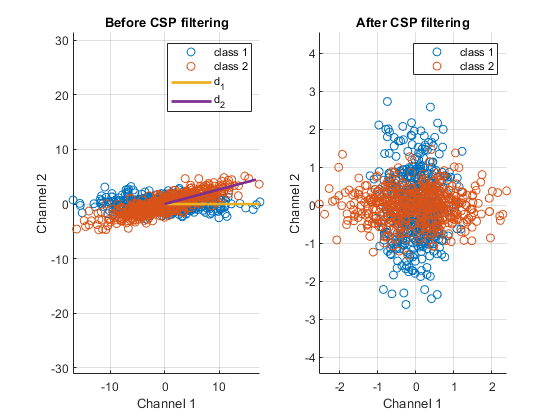

qf = 30;   % Quality factor.
pbr = 1;   % Passband ripple, dB.
for k = 1:3
    notchSpecs  = fdesign.notch('N,F0,Q,Ap',fo,cf * k,qf,pbr);
    notchFilt = design(notchSpecs,'IIR','SystemObject',true);

    data = notchFilt(data); 
end

#### Segmentation

EEG

% Window EEG signal into 500ms windows with 100ms overlap
window_size = 0.500;                        % window size s

f_mav = 0.0121

overlap = 0.100;                            % window overlap s

f_wl = 2.9498

[eeg_segments, egg_remaining_samples] = buffer(data(1,:),window_size*eeg_fs, overlap*eeg_fs)

f_zc = 59

EMG

% Window EMG signal into 250ms windows with 50ms overlap

f_ssc = 125

window_size = 0.250;                        % window size s
overlap = 0.050;                            % window overlap s

f_ar = -0.4711

[emg_segments, emg_remaining_samples] = buffer(data(1,:),window_size*emg_fs, overlap*emg_fs)

#### Feature extraction

EEG

Feature extraction: [https://se.mathworks.com/matlabcentral/fileexchange/72204-common-spatial-patterns-csp](https://se.mathworks.com/matlabcentral/fileexchange/72204-common-spatial-patterns-csp) 

% CSP

emg_features =     0.0121    2.9498   59.0000  125.0000   -0.4711


X1 = data1';    % Positive class data: X1~[C x T]
X2 = data2';    % Negative class data: X2~[C x T]
[W,l,A] = csp(X1,X2);
X1_CSP = W'*X1; % CSP filtered
X2_CSP = W'*X2; % CSP filtered

EMG

Feature extraction: [https://se.mathworks.com/matlabcentral/fileexchange/71514-emg-feature-extraction-toolbox](https://se.mathworks.com/matlabcentral/fileexchange/71514-emg-feature-extraction-toolbox) 

%{
% Options for the the feature extraction 
opts.thres = 0.01; 
opts.order = 1; % Defines output dimension
%}

f_mav = jfemg('mav', data) % Mean absolut value
f_wl = jfemg('wl', data) % Waveform length
f_zc = jfemg('zc', data) % Zero crossing
f_ssc = jfemg('ssc', data) % Slope sign change
opts.order = 1; % Defines output dimension
f_ar = jfemg('ar', data, opts) % Auto regressive

emg_feature_vector = [f_mav, f_wl, f_zc, f_ssc, f_ar]

#### Train classifier

Oversampling: [https://se.mathworks.com/matlabcentral/fileexchange/70315-smote-over-sampling](https://se.mathworks.com/matlabcentral/fileexchange/70315-smote-over-sampling)

maybe [https://se.mathworks.com/matlabcentral/fileexchange/75401-synthetic-minority-over-sampling-technique-smote](https://se.mathworks.com/matlabcentral/fileexchange/75401-synthetic-minority-over-sampling-technique-smote) ?

Save and load models: [https://se.mathworks.com/matlabcentral/answers/264160-how-to-save-and-reuse-a-trained-neural-network](https://se.mathworks.com/matlabcentral/answers/264160-how-to-save-and-reuse-a-trained-neural-network) 

EEG

% Fix class imbalance with Synthetic Minority Over-sampling Technique (SMOTE)
balanced_eeg_data = mySMOTE(unbalanced_data, 5, [0,1]) % unbalanced data, k neighbors, ordered labels

% Train classifier using 5 fold cross validation
eeg_classifier = fitcsvm(data, labels,"KernelFunction","rbf","KernelScale","auto","CrossVal","on","KFold",5) % RBF SVM
save("trained_classifiers\eeg_classifier.mat","eeg_classifier")

% Confusion matrix
predicted = predict(eeg_classifier, true);
eeg_confusion_matrix = confusionmat(true, predicted)
confusionchart(eeg_confusion_matrix)

EMG

% Fix class imbalance with Synthetic Minority Over-sampling Technique (SMOTE)
balanced_emg_data = mySMOTE(unbalanced_data, 5, [0,1,2]) % unbalanced data, k neighbors, ordered labels

% Train classifier using 5 fold cross validation
emg_classifier = fitcdiscr(data, labels,"DiscrimType","linear","CrossVal","on","KFold",5,"SaveMemory","on") % LDA
save("trained_classifiers\emg_classifier.mat","emg_classifier")

% Confusion matrix
predicted = predict(emg_classifier, true);
emg_confusion_matrix = confusionmat(true, predicted)
confusionchart(emg_confusion_matrix)

[https://www.jmlr.org/papers/volume11/ojala10a/ojala10a.pdf](https://www.jmlr.org/papers/volume11/ojala10a/ojala10a.pdf) 

[https://www.sciencedirect.com/science/article/pii/S2213158214000485](https://www.sciencedirect.com/science/article/pii/S2213158214000485) 

Response time

N/A

Turtlebot3 and gazebo

N/A